[t,X] = GenererX_2();
Xc = (X-mean(X))./std(X,1)*sqrt(size(X,1));

%for i=1:size(Xc,2)
    %subplot(7,1,i);
    %plot(t,Xc(:,i))
%end

A = Xc'*Xc

A = 	1.0e+04 *

    1.0000   -0.7528   -0.7707   -0.7109    0.9764   -0.0205    0.9690
   -0.7528    1.0000    0.9233    0.9140   -0.7521    0.3840   -0.7177
   -0.7707    0.9233    1.0000    0.9928   -0.7676    0.4640   -0.7309
   -0.7109    0.9140    0.9928    1.0000   -0.7031    0.5175   -0.6631
    0.9764   -0.7521   -0.7676   -0.7031    1.0000    0.0074    0.9965
   -0.0205    0.3840    0.4640    0.5175    0.0074    1.0000    0.0428
    0.9690   -0.7177   -0.7309   -0.6631    0.9965    0.0428    1.0000


corrcoef(Xc) %renvoie la même chose si le calcul est juste 

ans =     1.0000   -0.7528   -0.7707   -0.7109    0.9764   -0.0205    0.9690
   -0.7528    1.0000    0.9233    0.9140   -0.7521    0.3840   -0.7177
   -0.7707    0.9233    1.0000    0.9928   -0.7676    0.4640   -0.7309
   -0.7109    0.9140    0.9928    1.0000   -0.7031    0.5175   -0.6631
    0.9764   -0.7521   -0.7676   -0.7031    1.0000    0.0074    0.9965
   -0.0205    0.3840    0.4640    0.5175    0.0074    1.0000    0.0428
    0.9690   -0.7177   -0.7309   -0.6631    0.9965    0.0428    1.0000


[vecp,valp] = eig(A)

vecp =     0.0608   -0.0082   -0.8241   -0.0032    0.2771    0.2771    0.4044
   -0.0160    0.0001    0.0069    0.7723    0.4616    0.1621   -0.4049
   -0.2266   -0.7003   -0.0571   -0.4165    0.2497    0.2130   -0.4169
    0.1651    0.6531    0.0100   -0.4543    0.3132    0.2820   -0.4026
   -0.7384    0.1653    0.3291   -0.0206    0.2536    0.3008    0.4049
    0.0064   -0.0044   -0.0210    0.1478   -0.6260    0.7542   -0.1304
    0.6100   -0.2359    0.4569   -0.0378    0.3060    0.3357    0.3946


valp = 	1.0e+04 *

    0.0017         0         0         0         0         0         0
         0    0.0027         0         0         0         0         0
         0         0    0.0339         0         0         0         0
         0         0         0    0.0961         0         0         0
         0         0         0         0    0.2580         0         0
         0         0         0         0         0    1.4216         0
         0         0         0         0         0         0    5.1859


%vecp
%valp
[valp_trie,vec_tri] = sort(diag(valp),'descend');
vecp = vecp(:,vec_tri);
valp_trie

valp_trie = 	1.0e+04 *

    5.1859
    1.4216
    0.2580
    0.0961
    0.0339
    0.0027
    0.0017


vec_tri

vec_tri =      7
     6
     5
     4
     3
     2
     1


plot([1,2,3,4,5,6,7],valp_trie','+r') % 2 valeurs propres avant le "coude"
%donc 2 axes sont suffisant pour représenter pertinemment les données (dans
%le cas GenererX (4 dans le cas GenererX_2))

%Nbre de valeurs propres= nombre de signaux (u1, u2, u1², u2²
%sont 4 signaux différents )
P = Xc*vecp; % projection sur la base des vecteurs propres

%for i=1:7
    %subplot(7,1,i)
    %plot(t,P(:,i))
%end

%vp_princi = [valp_trie(1);valp_trie(2)]

[V,S,U] = svd(Xc,0);
V1 = V(:,1:4);
S1 = S(1:4,1:4);
U1 = U(:,1:4);
Xc1 = V1*S1*U1'

Xc1 =   -10.5507    1.4834   -2.1078   -3.9977  -11.1707  -16.8335  -11.9553
  -10.3318   -2.7881   -2.1150   -3.9240  -10.5872   -7.7275  -11.5013
   -9.8451   -2.1006   -1.4960   -3.2252  -10.3302  -15.2264  -11.1008
   -8.6809   -5.1205   -2.0220   -3.6156   -8.9787  -11.0316   -9.7939
   -9.7105    6.9670   -2.1230   -3.7948  -10.1712   -7.9307  -10.8399
   -7.3767   -1.6710   -1.9869   -3.3012   -7.4785   -2.4057   -8.1806
   -8.8677   -4.0219   -2.3563   -3.9638   -9.0296   -5.5966   -9.8953
   -8.6838    0.3488   -2.1665   -3.7163   -8.9723   -6.9092   -9.7125
   -8.7413   -7.1625   -2.1636   -3.8453   -9.2127  -18.1030  -10.0406
   -8.9328   -2.8569   -1.8048   -3.3781   -9.1809   -7.8973   -9.9709


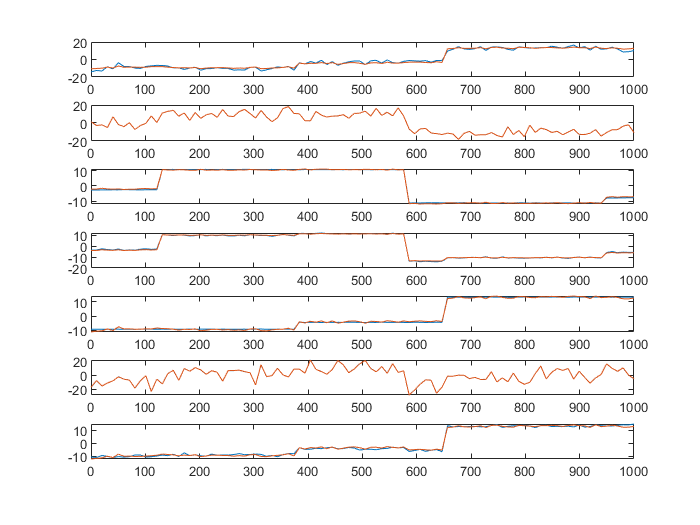


for i=1:7
    subplot(7,1,i)
    plot(t,Xc(:,i),t,Xc1(:,i))
end

%Taux de réduction de 100*2/100*7=2/7 (+ vp négligeables)